# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 2-a. **$z$**-Transform의 이해**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2022b 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : Delay operator $z^{-1}$의 이해 

Topic 1에서는 MATLAB 환경에서 inverse $z$-transform을 연산하는 방법과 delay 연산자인 $z^{-1}$의 역할에 대해 이해해봅니다. 

이를 위해 교재에서 제공한 예제들과 유사하게 [Symbolic Math Toolbox](https://kr.mathworks.com/products/symbolic.html)을 활용하고자 합니다.

$\mathtt{syms}$를 이용하여 $k$, $z$ 등의 변수들을 symbolic variable로써 정의합니다.

syms k z

이제 ${\mathtt{iztrans}}$ 함수를 이용하여


$$F^d(z)=\frac{\sin(0.5)z}{z^2-2\cos(0.5)z+1}=\mathcal{Z}^{-1}(\sin(0.5k))$$


의 inverse $z$-transform $f^d(k) = {\mathcal{Z}}^{-1}[F^d(z)]$을 아래와 같이 계산합니다.

Fdz = (z*sin(0.5))/(z^2 - 2*z*cos(0.5)+1);
fdk = iztrans(Fdz,k); 
fdk = simplify(fdk);    

유사한 방식으로 


$$G^d(z)=z^{-1}F^d(z)$$


의 inverse $z$-transform $g^d(k) = {\mathcal{Z}}^{-1}[G^d(z)]$을 아래와 같이 계산합니다.

Gdz = Fdz * z^-1;
gdk = iztrans(Gdz,k);
gdk = simplify(gdk);

$z$-transform에서 $z^{-1}$가 가지는 의미를 생각해볼 때, 두 신호는


$$g^d(k)=f^d(k-1){\bf 1}^d(k-1)$$


의 관계를 가짐을 예상할 수 있습니다. (여기서 ${\bf 1}^d(k)$는 이산 시간에서의 단위 응답 신호(unit step signal)입니다.)

아래 코드를 실행하여 실제로 그러한지를 확인할 수 있습니다.

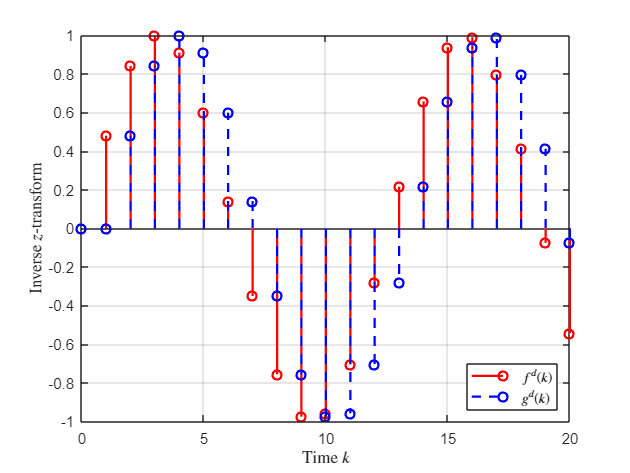

N = 20;
fdk_data = double(subs(fdk,k,0:N));     
gdk_data = double(subs(gdk,k,0:N));

fig = figure();     
stem(0:N,fdk_data,'r','LineWidth',1.5);
hold on;
stem(0:N,gdk_data,'--b','LineWidth',1.5);
grid on;
xlabel('Time $k$','Interpreter','latex');
ylabel('Inverse $z$-transform', 'Interpreter','latex');
legend('$f^{d}(k)$','$g^{d}(k)$','Interpreter','latex','Location','southeast');

### Topic 2 : 연속 시간 신호의 이산화

Topic 2에서는 MATLAB 작업 공간 상에서 연속 시간에서 구현된 신호를 이산화하는 방법에 대해 알아보겠습니다. 

예시로 symbolic variable로 표현된 연속 시간 $t$와, 이를 이용하여 정의한 $f(t) = \sin(t)$를 생각해봅시다. 

syms t;
f = sin(t);

이제 샘플링 주기 $T=(\pi/6)~[{\rm sec}]$로 하고 샘플 시간 $t = kT$마다 $f(t)=\sin(t)$를 샘플링한 이산 시간 신호 $f^d(k) = \sin (kT)$를 다음과 같이 얻습니다.

T = pi/6;
fdk = subs(f,t,k*T);

$f(t)$와 $f^d(k)$를 하나의 화면에 그리면 다음과 같으며, 예상한 대로 샘플링이 수행되었음을 확인할 수 있습니다.

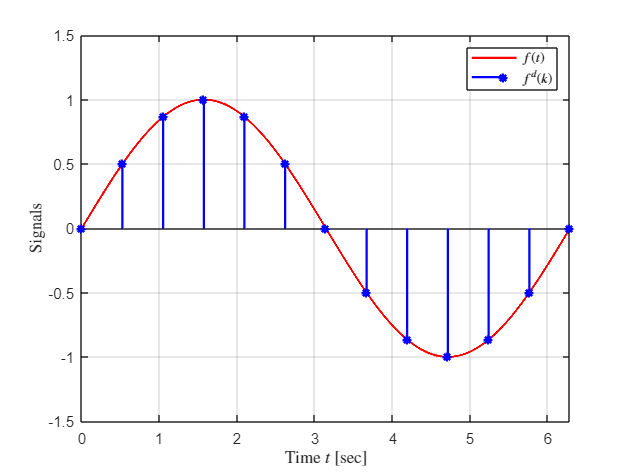

N = 12;
fdk_data = double(subs(fdk,k,0:N));

figure();
dt = 0.001;
f_data = subs(f,t,0:dt:2*pi);
plot(0:dt:2*pi,f_data,'r','LineWidth',1.5);
hold on;
stem(0:T:2*pi,fdk_data,'*b','LineWidth',1.5);
grid on;
xlabel('Time $t$ [sec]','Interpreter','latex');
ylabel('Signals','Interpreter','latex');
xlim([0,2*pi]); 
ylim([-1.5,1.5]);
legend('$f(t)$','$f^d(k)$','Interpreter','latex','Location','northeast'); 

### Topic 3 : $z$-transform의 선형성

Topic 3에서는 $z$-transform $\mathcal{Z}[\cdot]$을 연속 시간의 신호를 입력으로 가지는 함수라고 생각하고, 이 함수의 선형성에 대해 살펴보겠습니다.

이는 어떠한 스칼라값 $a$, $b$와 어떠한 두 이산 시간 신호 $f^d(k)$, $g^d(k)$에 대하여도, $z$-transform은 다음의 수식을 항상 만족함을 의미합니다. 


$${\mathcal{Z}}[a\cdot f^d(k)+b\cdot g^d(k)] = a\cdot \mathcal{Z}[f^d(k)]+b\cdot \mathcal{Z}[g^d(k)]$$


Topic 2의 샘플링 주기 $T=(\pi/6)~[{\rm sec}]$에 대해 정의된 두 이산 시간 신호들 $f^d(k)=\sin(kT)$, $g^d(k)=\cos(kT)$를 생각해봅시다.

fdk = sin(k*T);
gdk = cos(k*T);

위 신호의 선형 결합인 $h_1^d(k)=1\cdot f^d(k)+2\cdot g^d(k)$는 다음과 같이 얻을 수 있습니다..

h1dk = 1*fdk + 2*gdk;

지금부터는 $F^d(z):=\mathcal{Z}[f^d(k)]$, $G^d(z):=\mathcal{Z}[g^d(k)]$에 대하여 


$$h_2^d(k):=\mathcal{Z}^{-1}(1\cdot F^d(z)+2\cdot G^d(z))$$


로 정의된 이산 시간 신호 $h_2^d(k)$가 위에서 얻은 $h_1^d(k)=1\cdot f^d(k)+2\cdot g^d(k)$와 동일함을 보이도록 하겠습니다. 

이를 위해 $\mathtt{iztrans}$ 함수를 이용하여 $h_2^d(k)$를 다음과 같이 얻습니다.

Fdz = ztrans(fdk,z); 
Gdz = ztrans(gdk,z);

h2dk = iztrans(1*Fdz + 2*Gdz,k);
h2dk = simplify(h2dk);

이제 두 이산 시간 신호들인 $h_1^d(k)$와 $h_2^d(k)$를 하나의 그래프로 동시에 그려서 두 신호가 동일함을 확인해봅시다.

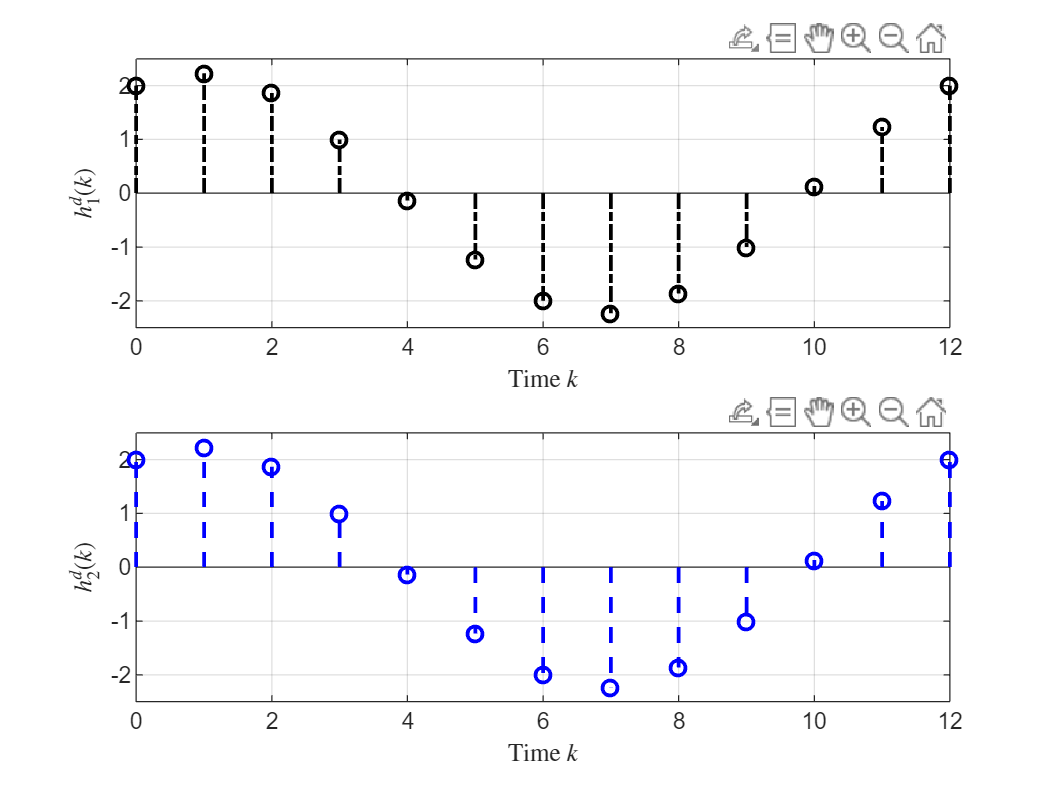

N = 12;
h1dk_data = double(subs(h1dk,k,0:N));
h2dk_data = double(subs(h2dk,k,0:N));

figure();
subplot(2,1,1);
stem(0:N,h1dk_data,'-.k','LineWidth',1.5);
grid on;
xlim([0,N]);
ylim([-2.5,2.5]);
xlabel('Time $k$','Interpreter','latex');
ylabel('$h_1^d(k)$','Interpreter','latex');
hold on;

subplot(2,1,2);
stem(0:N,h2dk_data,'--b','LineWidth',1.5);
grid on;
xlim([0,N]);
ylim([-2.5,2.5]);
xlabel('Time $k$','Interpreter','latex');

ylabel('$h_2^d(k)$','Interpreter','latex');

### Topic 4 : $z$-domain에서 표현된 이산 시간 시스템의 계단 응답 구하기

Topic 4에서는 MATLAB/Simulink 환경에서


$$G^d(z)=\frac{z}{z^2-1.7z+0.72}$$


를 전달함수로 가지는 이산 시간 시스템의 계단 응답(step response)를 구하는 3가지 방법에 대해 알아보겠습니다. 

**계단 응답을 계산하는 첫 번째 방법은 MATLAB에서 제공하는 **$\mathtt{step}$** 함수를 사용하는 방식입니다.**

이를 위해 이산 시간 전달함수 $G^d(z)$를 ${\mathtt{tf}}$ 모델 객체의 형태로 구현합시다. 

numGdz = [1 0];
denGdz = [1 -1.7 0.72];
Gdz = tf(numGdz,denGdz,T);

$\mathtt{tf}$ 함수는 $z$에 대한 다항식인 분자식(numerator)과 분모식(denominator)의 계수들을 모아놓은 열벡터 $[1~0]$과 $[1~-1.7~0.72]$를 입력으로 합니다. 

한편 마지막 입력인자인 $T$는 샘플링 주기이며, 만약 샘플링 주기가 정해지지 않았다면 $-1$을 대입하여도 됩니다.

이제 $\mathtt{step}$ 함수를 사용하여 계단 응답의 결과를 $y^d_1(k)$로 저장합니다.

N = 50;
y1dk = step(Gdz,0:T:T*N);

**계단 응답을 계산하는 두 번째 방법은 inverse **$z$**-transform을 활용하는 방식입니다. **

이를 위해 단위 계단 함수 $u^d(k)={\bf 1}^d(k)$의 $z$-transform에 해당하는 


$$U^d(z)={\mathcal{Z}}[{\bf 1}^d(k)] = \frac{1}{z-1}$$


을 ${\mathtt{tf}}$ 모델 객체의 형태로 아래와 같이 정의하고, 여기에 시스템의 전달함수인 $G^d(z)$를 곱하여 출력 신호의 $z$-transform인 $Y_2^d(z)$를 얻도록 합시다. 

Udz = tf(1,[1 -1],-1);
Y2dz = Gdz*Udz;

이제 앞선 topic들과 동일한 방법을 통해 $Y_2^d(z)=G^d(z)U^d(z)$의 inverse $z$-transform을 계산합니다.

[numY2dz,denY2dz] = tfdata(Y2dz);
Y2dz_sym = poly2sym(cell2mat(numY2dz),z)/poly2sym(cell2mat(denY2dz),z);
% 위의 코드의 결과는, Y2dz_sym = (numY2dz(1)*z^2 + numY2dz(2)*z +
% numY2dz(3))/(denY2dz(1)*z^2 + denY2dz(2)*z + denY2dz(3))과 동일합니다.

y2dk = iztrans(Y2dz_sym,k);
y2dk = double(subs(y2dk,k,0:N));

**계단 응답을 계산하는 마지막 방법은 Simulink 환경에서 시간 영역의 모의실험을 수행하는 방법입니다.**

이를 위해 미리 작성해둔 Simulink 파일을 열어봅시다.

open('sim_topic4.slx');

Simulink 파일은 아래 그림과 같이 구성되어 있으며, 이 중 **Discrete Transfer Function** 블록을 통해 전달함수로 표현된 이산 시간 시스템을 구현할 수 있습니다.

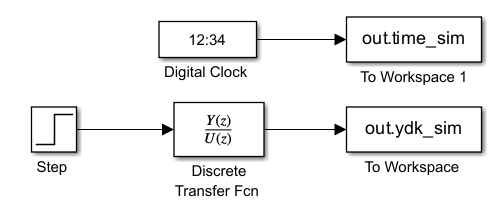

Discrete transfer function 블록을 더블 클릭하면, 다음의 창이 열립니다. 

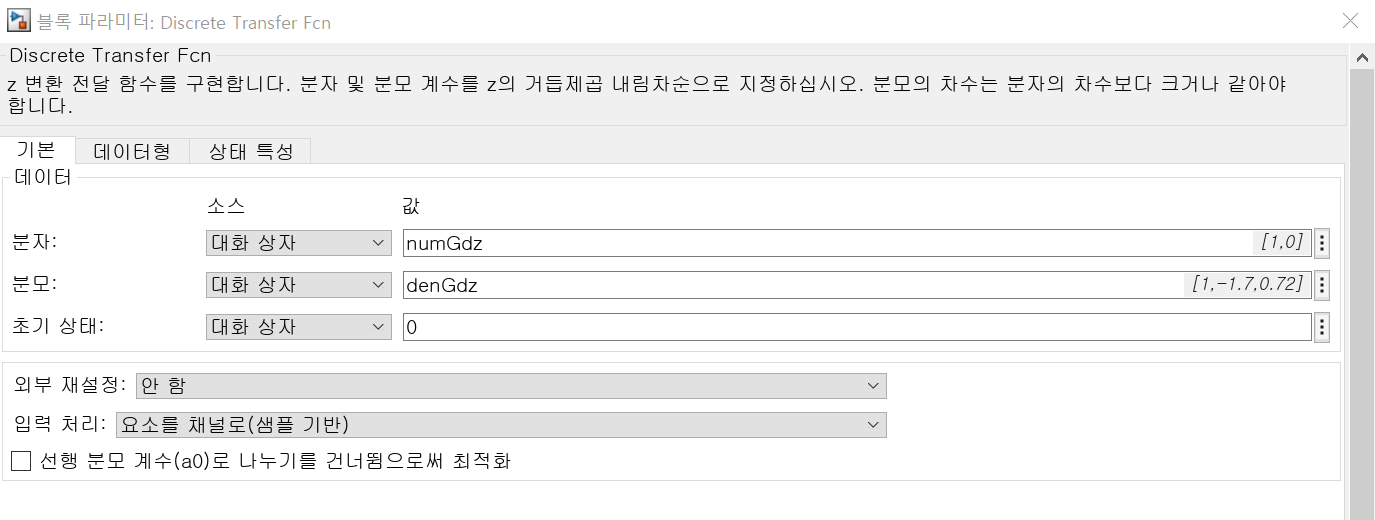

여기서 "분자", "분모" 데이터 입력칸에 앞서 정의한 전달함수의 분자식, 분모식의 계수 벡터인 numGdz, denGdz를 각각 입력하면, 이산시간 전달함수 $G^d(z)$를 Simulink 환경에서 구현할 수 있게 됩니다.

이제 ${\mathtt{sim}}$ 함수를 이용하여 Simulink 시뮬레이션을 수행하고 그 결과를 **To Workspace** 블록들을 이용하여 MATLAB의 작업 공간에 저장합시다.

sim('sim_topic4.slx');
simout = ans;
time_sim = simout.time_sim;
y3dk = simout.ydk_sim;

이제 그림을 통해 모든 결과가 동일함을 확인해봅시다. 

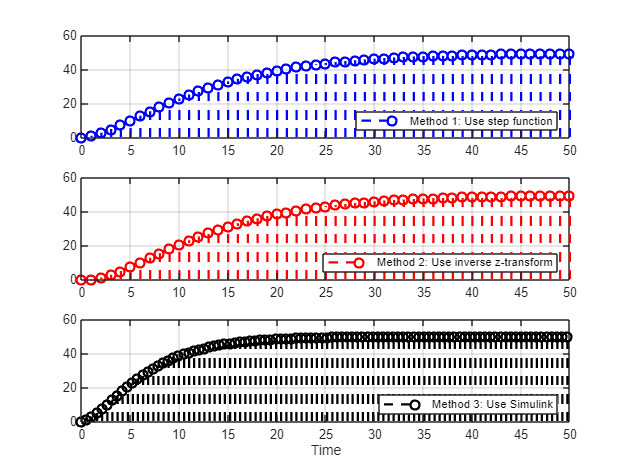

figure();
title('Step responses')
subplot(3,1,1)
stem(0:N,y1dk,'--b','LineWidth',1.5);
grid on;
legend('Method 1: Use step function','Location','southeast');
subplot(3,1,2)
stem(0:N,y2dk,'--r','LineWidth',1.5);
grid on;
legend('Method 2: Use inverse z-transform','Location','southeast');
subplot(3,1,3)
stem(time_sim,y3dk,'--k','LineWidth',1.5);
legend('Method 3: Use Simulink','Location','southeast');
grid on;
xlim([0,N]);
xlabel('Time');